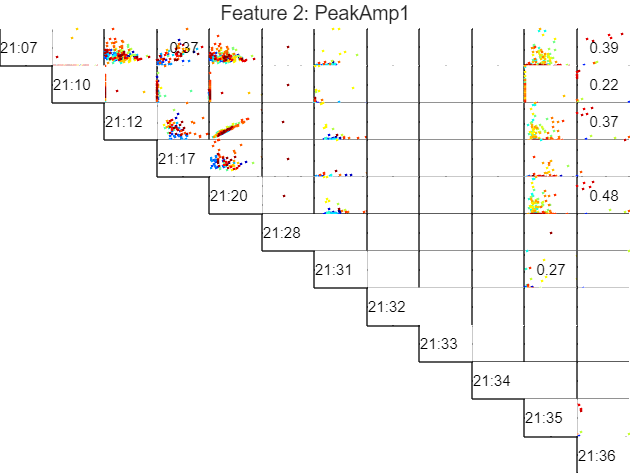

Features = DFD_FeatureTable_FreqDomain;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;  
selectedFeature = 2;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames); 

disp(num2str(R2, '%.2f  '));

0.00  0.01  0.04  0.37  0.02   NaN  0.18   NaN   NaN   NaN  0.03  0.39
0.00  0.00  0.00  0.00  0.00   NaN  0.01   NaN   NaN   NaN  0.00  0.22
0.00  0.00  0.00  0.03  0.94   NaN  0.07   NaN   NaN   NaN  0.00  0.37
0.00  0.00  0.00  0.00  0.02   NaN  0.03   NaN   NaN   NaN  0.05  1.00
0.00  0.00  0.00  0.00  0.00   NaN  0.03   NaN   NaN   NaN  0.00  0.48
0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN  0.27  1.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row number
selectedFeature = selectedFeature + 13;
FeatureNames = FeatureNames_Combined;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     4    12



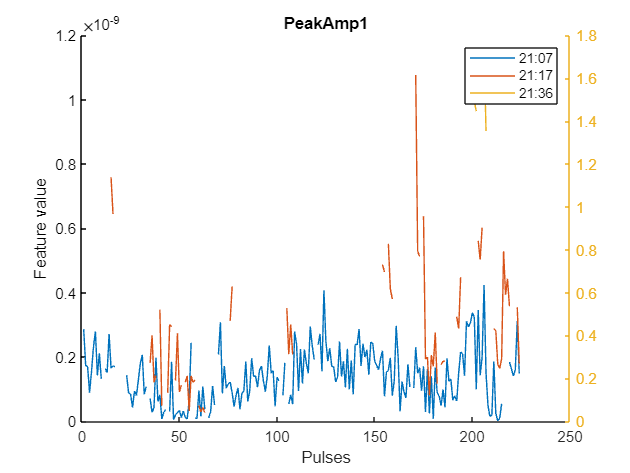

figure(); hold on;
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedSignals};
secondaryAxisArrayIndex = [3];
for i = 1:numOfSelectedSignals
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    end
    plot(selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
legend(leg);

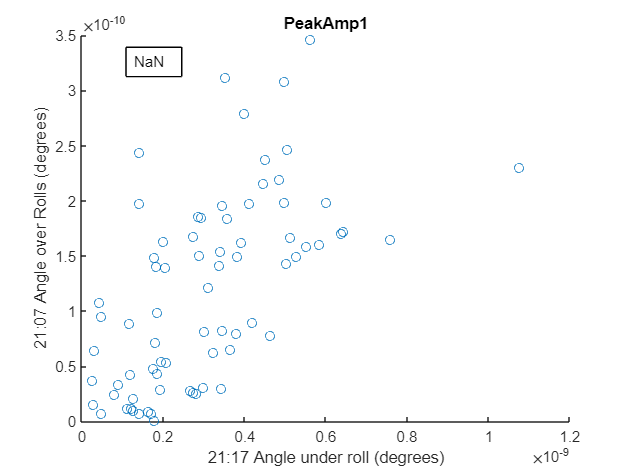

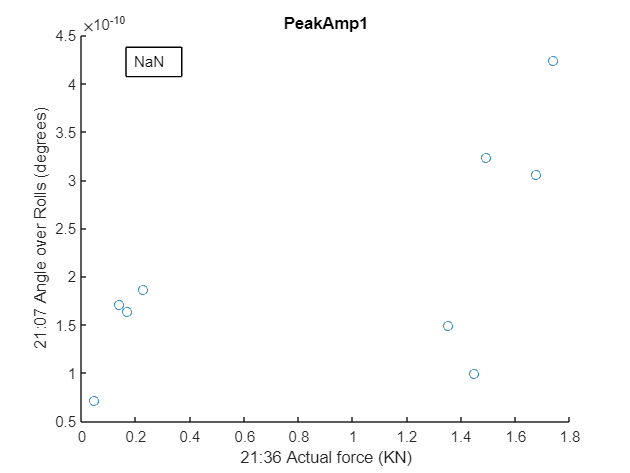

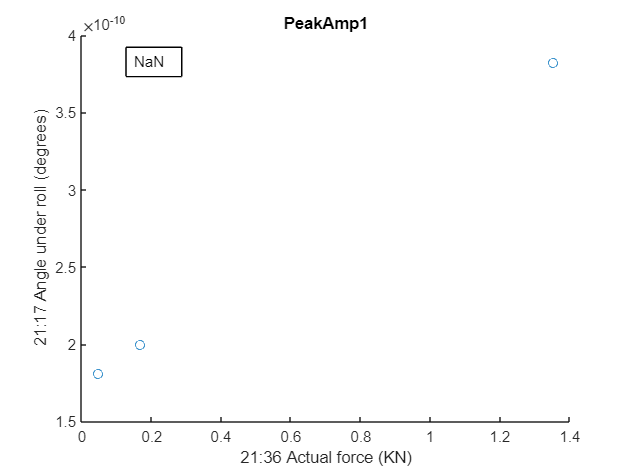

for index1 = 1 : numOfSelectedSignals
    for index2 = index1 + 1 : numOfSelectedSignals
        fnPlotModel(selectedSignalData{index1}, ...
            selectedSignalData{index2}, ...
            FeatureNames(selectedFeature), ...
            sensorNames(selectedSignalArray(index1)), ...
            sensorNames(selectedSignalArray(index2)));
    end
end